# **Vortex Interaction Simulation**

## Vortex Trajectories

% circulation values
global gamma1 gamma2 gamma3 gamma4
gamma1 = -1;
gamma2 = 1;
gamma3 = 1;
gamma4 = -1;

% initial conditions/locations (x, y spatial coordinates)
x1_0 = -1;
y1_0 = 5;
x2_0 = 1;
y2_0 = 5;
x3_0 = -1;
y3_0 = -5;
x4_0 = 1;
y4_0 = -5;

IC = [x1_0,y1_0,x2_0,y2_0,x3_0,y3_0,x4_0,y4_0];

% integration duration (s)
t0 = 0;
tf = 120;

tspan = [t0,tf];

% integrate the vortex motion equation
[time, state_values] = ode45(@vortex_motion,tspan,IC);
x1 = state_values(:,1);
y1 = state_values(:,2);
x2 = state_values(:,3);
y2 = state_values(:,4);
x3 = state_values(:,5);
y3 = state_values(:,6);
x4 = state_values(:,7);
y4 = state_values(:,8);

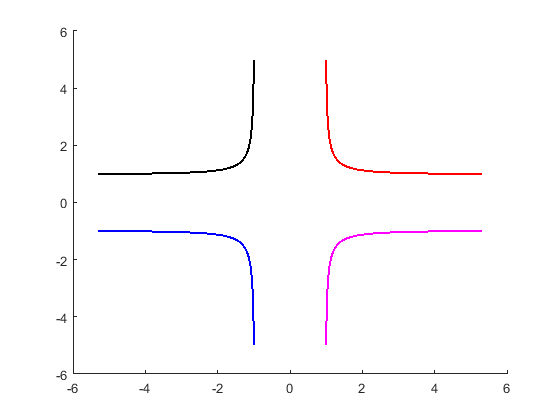

% animate trajectories
cla
l1 = animatedline;
l1.LineWidth = 1.5;

l2 = animatedline;
l2.Color = 'r';
l2.LineWidth = 1.5;

l3 = animatedline;
l3.Color = 'b';
l3.LineWidth = 1.5;

l4 = animatedline;
l4.Color = 'm';
l4.LineWidth = 1.5;

axis([-6,6,-6,6])

for i = 1:length(x1)
    addpoints(l1,x1(i),y1(i));
    addpoints(l2,x2(i),y2(i));
    addpoints(l3,x3(i),y3(i));
    addpoints(l4,x4(i),y4(i));
    drawnow
end

## Vortex Vector Field

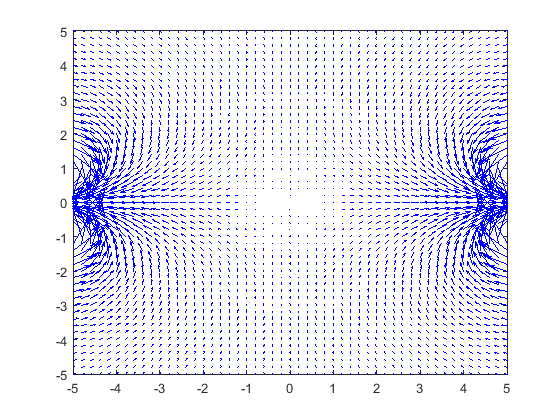

[x, y] = meshgrid(-5:0.2:5);
z = x + 1i*y;

for i = 1:length(x1)
%     % complex potential equations (derivative for potential vortex)
    vortex1 = -1i.*gamma1 ./ (2*pi.*(z - x1(i) - y1(i)*1i));
    vortex2 = -1i.*gamma2 ./ (2*pi.*(z - x2(i) - y2(i)*1i));
    vortex3 = -1i.*gamma3 ./ (2*pi.*(z - x3(i) - y3(i)*1i));
    vortex4 = -1i.*gamma4 ./ (2*pi.*(z - x4(i) - y4(i)*1i));
    
    dwdz = vortex1 + vortex2 + vortex3 + vortex4;
    
    u = real(dwdz);
    u(isinf(u)) = 0;
    
    v = -imag(dwdz);
    v(isinf(v)) = 0;
    
    quiver(real(z),imag(z),u,v,8,'b',"LineWidth",1)
    
    hold on
    xlocs = [x1(i), x2(i), x3(i), x4(i)];
    ylocs = [y1(i), y2(i), y3(i), y4(i)];
    scatter(xlocs,ylocs,'SizeData',100,"LineWidth",1,"MarkerEdgeColor",'k', ...
        "MarkerFaceColor",'r',"MarkerFaceAlpha",0.6)
    hold off
    axis([-5 5 -5 5])
    pause(0.5)
end

function dsdt = vortex_motion(t,s)

% circulation values
global gamma1 gamma2 gamma3 gamma4

% distance between vortices
r12 = norm([s(3),s(4)] - [s(1),s(2)]);
r13 = norm([s(5),s(6)] - [s(1),s(2)]);
r14 = norm([s(7),s(8)] - [s(1),s(2)]);
r21 = r12;
r23 = norm([s(5),s(6)] - [s(3),s(4)]);
r24 = norm([s(7),s(8)] - [s(3),s(4)]);
r31 = r13;
r32 = r23;
r34 = norm([s(7),s(8)] - [s(5),s(6)]);
r41 = r14;
r42 = r24;
r43 = r34;

% ODEs
dx1dt = -1/(2*pi) * (gamma2/r12^2*(s(2)-s(4)) + gamma3/r13^2*(s(2)-s(6)) ...
    + gamma4/r14^2*(s(2)-s(8)));
dy1dt = 1/(2*pi) * (gamma2/r12^2*(s(1)-s(3)) + gamma3/r13^2*(s(1)-s(5)) ...
    + gamma4/r14^2*(s(1)-s(7)));
dx2dt = -1/(2*pi) * (gamma1/r21^2*(s(4)-s(2)) + gamma3/r23^2*(s(4)-s(6)) ...
    + gamma4/r24^2*(s(4)-s(8)));
dy2dt = 1/(2*pi) * (gamma1/r21^2*(s(3)-s(1)) + gamma3/r23^2*(s(3)-s(5)) ...
    + gamma4/r24^2*(s(3)-s(7)));
dx3dt = -1/(2*pi) * (gamma1/r31^2*(s(6)-s(2)) + gamma2/r32^2*(s(6)-s(4)) ...
    + gamma4/r34^2*(s(6)-s(8)));
dy3dt = 1/(2*pi) * (gamma1/r31^2*(s(5)-s(1)) + gamma2/r32^2*(s(5)-s(3)) ...
    + gamma4/r34^2*(s(5)-s(7)));
dx4dt = -1/(2*pi) * (gamma1/r41^2*(s(8)-s(2)) + gamma2/r42^2*(s(8)-s(4)) ...
    + gamma3/r43^2*(s(8)-s(6)));
dy4dt = 1/(2*pi) * (gamma1/r41^2*(s(7)-s(1)) + gamma2/r42^2*(s(7)-s(3)) ...
    + gamma3/r43^2*(s(7)-s(5)));

dsdt = [dx1dt; dy1dt; dx2dt; dy2dt; dx3dt; dy3dt; dx4dt; dy4dt];
end